%Fig 10.1
% This code plots the signal from the pneuma simulator stored in the
% file CARDIORESPIRATORY1.mat. The variables include: Time, State Drive SI, HR, ABP, Ppl, PaCO2,
% SaO2, Breathing Frequency BF, Tidal Volume Vt,
% Total Ventilatory Drive DTotal

% Cheyne-Stokes with central sleep apnea is simulated here. 
range=[1515 1715];

range =         1515        1715


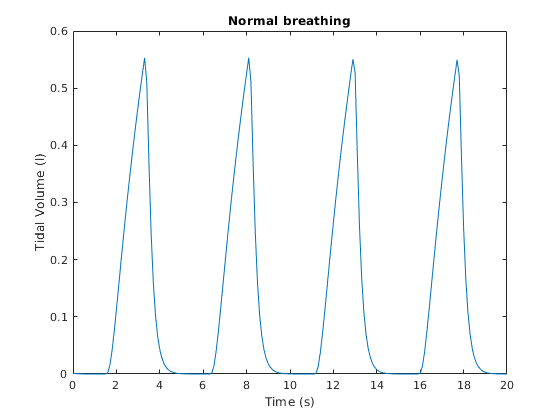

load('CARDIORESPIRATORY1_normal.mat', 'CARDIORESPIRATORY')
figure
plot(CARDIORESPIRATORY(1,range(1):range(2))-CARDIORESPIRATORY(1,range(1)),CARDIORESPIRATORY(9,range(1):range(2)))
xlabel('Time (s)')
ylabel('Tidal Volume (l)')
title('Normal breathing')

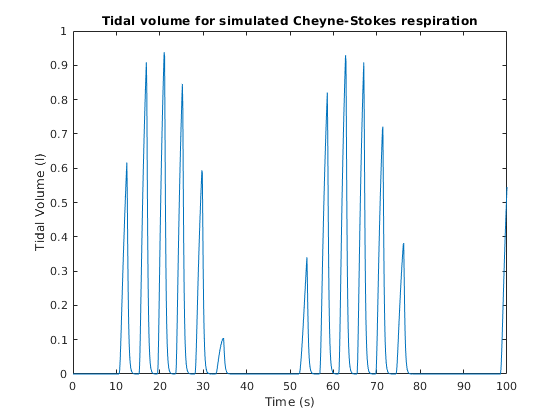

%Fig 10.2
% This function plots the signal from the pneuma simulator stored in the
% file CARDIORESPIRATORY1.mat. The variables include: Time, State Drive SI, HR, ABP, Ppl, PaCO2,
% SaO2, Breathing Frequency BF, Tidal Volume Vt,
% Total Ventilatory Drive DTotal

% Cheyne-Stokes with central sleep apnea is simulated here. 

range=[22500 23500];
load('CARDIORESPIRATORY1_CS.mat', 'CARDIORESPIRATORY')
figure
plot(CARDIORESPIRATORY(1,range(1):range(2))-CARDIORESPIRATORY(1,range(1)),CARDIORESPIRATORY(9,range(1):range(2)))
xlabel('Time (s)')
ylabel('Tidal Volume (l)')
title('Tidal volume for simulated Cheyne-Stokes respiration')

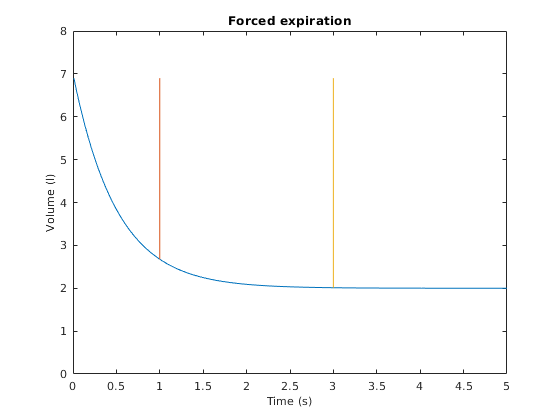

% Fig 10.15
fs=100;
t=1/fs:1/fs:500/fs;
y=2+5*exp(-2*t);
plot(t,y)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Volume (l)', 'FontSize', 10)
title('Forced expiration')
ylim([0,8])
hold on
plot([1,1],[y(1*fs),max(y)])
%annotation('arrow', [1,1],[y(1*fs),max(y)])
plot([3,3],[y(3*fs),max(y)])

%text()